% Read table 
clear
tic

T = readtable('dowPortfolio.xlsx');

% writetable (T, 'dowPortfolio.xlsx') ;
TT = table2timetable (T);
pricesTT = TT(:,2:end) ;
head (pricesTT)

ans = 8×30 timetable
       Dates        AA       AIG      AXP      BA        C       CAT      DD       DIS      GE       GM       HD       HON      HPQ      IBM     INTC      JNJ      JPM      KO       MCD      MMM      MO       MRK     MSFT      PFE      PG        T       UTX      VZ       WMT      XOM 
    ___________    _____    _____    _____    _____    _____    


% Initial weights
warmUpPeriod = 40;
warmUpTT = pricesTT (1: warmUpPeriod, :) ;
nAssets = size(pricesTT.Variables, 2) ;
current_weights = zeros (1, nAssets) ;
equalWeightInitial = equalWeightFcn (current_weights, warmUpTT) ;

% Create strategy

rebalFreq = 21 ;
lookback = [40 126] ;
TransactionCosts = 0/100 ;

equalWeightStrategy = backtestStrategy ("Equal Weighted", ...
    @equalWeightFcn, "RebalanceFrequency", rebalFreq, "LookbackWindow", 0, "TransactionCosts",TransactionCosts,"InitialWeights", equalWeightInitial)

equalWeightStrategy =   backtestStrategy with properties:

                  Name: "Equal_Weighted"
          RebalanceFcn: @equalWeightFcn
    RebalanceFrequency: 21
      TransactionCosts: 0
        LookbackWindow: 0
        InitialWeights: [0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333 0.0333]



% Define backtesting engine

AnnualRiskfreeRate = 0/100 ;
backtester = backtestEngine (equalWeightStrategy, "RiskFreeRate", AnnualRiskfreeRate)

backtester =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 0
           CashBorrowRate: 0
          RatesConvention: "Annualized"
                    Basis: 0
    InitialPortfolioValue: 10000
                NumAssets: []
                  Returns: []
                Positions: []
                 Turnover: []
                  BuyCost: []
                 SellCost: []



% Run backtest
backtester = runBacktest (backtester, pricesTT, 'Start', warmUpPeriod)

backtester =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 0
           CashBorrowRate: 0
          RatesConvention: "Annualized"
                    Basis: 0
    InitialPortfolioValue: 10000
                NumAssets: 30
                  Returns: [211×1 timetable]
                Positions: [1×1 struct]
                 Turnover: [211×1 timetable]
                  BuyCost: [211×1 timetable]
                 SellCost: [211×1 timetable]



% Examine backtest results

summaryBacktest = summary (backtester)

summaryBacktest = 9×1 table
                       Equal_Weighted
                       ______________

    TotalReturn             0.16465  
    SharpeRatio              0.1181  
    Volatility            0.0063007  
    AverageTurnover      0.00081741  
    MaxTurnover            0.027824  
    AverageReturn        0.00074237  
    MaxDrawdown            0.074839  
    AverageBuyCost                0  
    AverageSellCost               0  


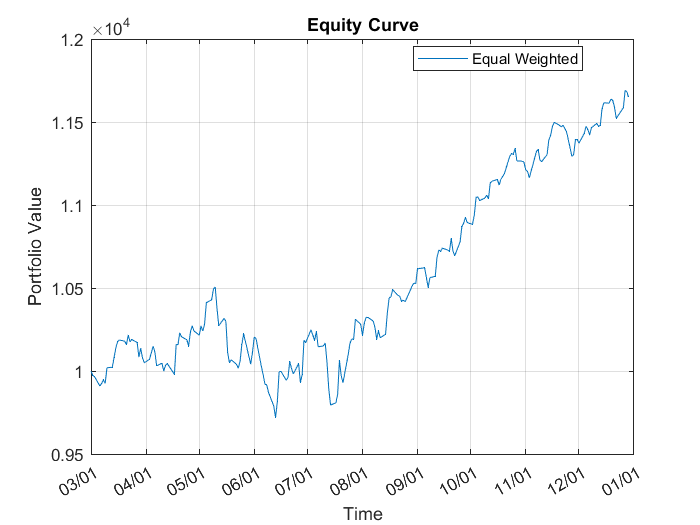

equityCurve (backtester)


toc

Elapsed time is 0.913827 seconds.


Local Functions

function new_weights = equalWeightFcn(current_weights, pricesTT)
% Equal-weighted portfolio allocation

nAssets = size(pricesTT.Variables, 2);
new_weights = ones(1,nAssets);
new_weights = new_weights / sum(new_weights);

end